t = 0:1/100:10-1/100;                     % Time vector
x = cos(2*pi*t)

x =     1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628    0.0000   -0.0628   -0.1253   -0.1874   -0.2487   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298   -0.9511   -0.9686   -0.9823   -0.9921   -0.9980


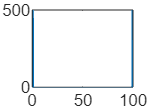

y = fft(x);                               % Compute DFT of x
m = abs(y); 
f = (0:length(y)-1)*100/length(y);        % Frequency vector
figure(1)
plot(f,m)

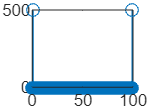

figure(2)
stem(f,m)

x = cos(2*pi*0.3*t)

x =     1.0000    0.9998    0.9993    0.9984    0.9972    0.9956    0.9936    0.9913    0.9887    0.9856    0.9823    0.9786    0.9745    0.9701    0.9654    0.9603    0.9549    0.9491    0.9430    0.9365    0.9298    0.9227    0.9152    0.9075    0.8994    0.8910    0.8823    0.8733    0.8639    0.8543    0.8443    0.8341    0.8235    0.8127    0.8016    0.7902    0.7785    0.7665    0.7543    0.7417    0.7290    0.7159    0.7026    0.6891    0.6753    0.6613    0.6471    0.6326    0.6179    0.6029


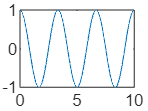

figure(4)
plot(t,x)


y = fft(x)

y = 1.0e+02 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   5.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


fk=0.3*t

fk =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0180    0.0210    0.0240    0.0270    0.0300    0.0330    0.0360    0.0390    0.0420    0.0450    0.0480    0.0510    0.0540    0.0570    0.0600    0.0630    0.0660    0.0690    0.0720    0.0750    0.0780    0.0810    0.0840    0.0870    0.0900    0.0930    0.0960    0.0990    0.1020    0.1050    0.1080    0.1110    0.1140    0.1170    0.1200    0.1230    0.1260    0.1290    0.1320    0.1350    0.1380    0.1410    0.1440    0.1470


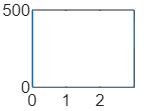

figure(3)
plot(fk,abs(y))

% see example on supressing sidelobes

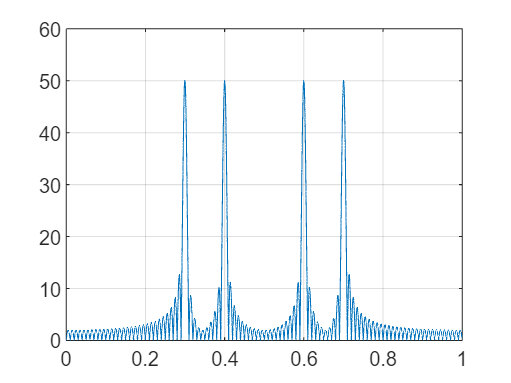

N=100;
n = 0:N-1;
NFFT = 10000;
k=0:NFFT-1;
wk=2*pi/NFFT*k;
fk=wk/(2*pi);
f1=0.3;
f2=0.4;
x=cos(2*pi*f1*n) + cos(2*pi*f2*n);
X = fft(x,NFFT);% NFFT?
figure(3)
plot(fk,abs(X)),grid


% hamming window
win=hamming(N);
win = win'; % x is row vector

win =     0.0800    0.0809    0.0837    0.0883    0.0947    0.1030    0.1130    0.1247    0.1380    0.1530    0.1696    0.1876    0.2071    0.2279    0.2499    0.2732    0.2975    0.3228    0.3489    0.3758    0.4034    0.4316    0.4601    0.4890    0.5181    0.5473    0.5765    0.6055    0.6342    0.6626    0.6905    0.7177    0.7443    0.7700    0.7948    0.8186    0.8412    0.8627    0.8828    0.9016    0.9189    0.9347    0.9489    0.9614    0.9723    0.9814    0.9887    0.9942    0.9979    0.9998


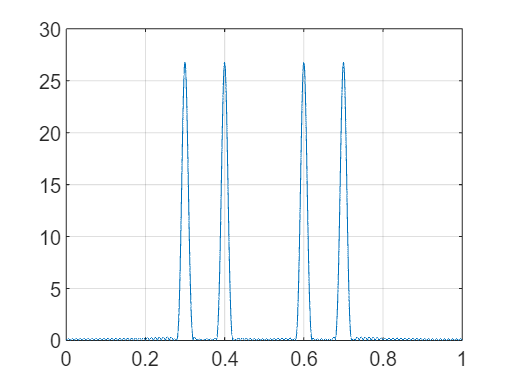

X = fft(x.*win,NFFT);% NFFT?
figure(4)
plot(fk,abs(X)),grid

N=100;
n = 0:N-1; % time domain sampling
NFFT = 10000; 
k=0:NFFT-1; %  freq domain sampling
wk=2*pi/NFFT*k;
fk=wk/(2*pi);
f1=0.399 % changef1 closer to f2

f1 = 0.3990

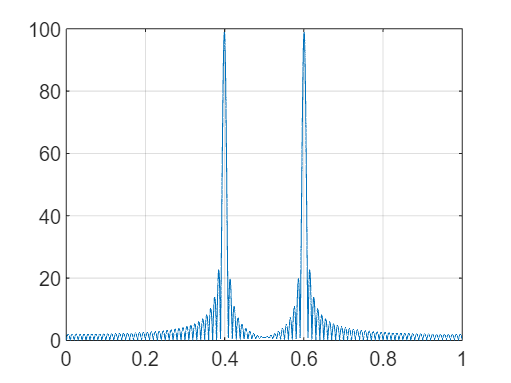

f2=0.4;
x=cos(2*pi*f1*n) + cos(2*pi*f2*n);
X = fft(x,NFFT);% NFFT?
figure(3)
plot(fk,abs(X)),grid % plot in freq domain

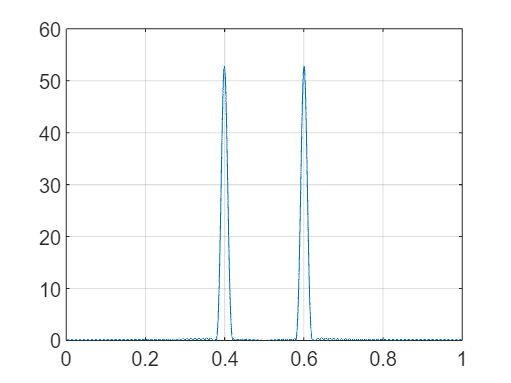


% hamming window
win=hamming(N);
win = win'; % x is row vector
X = fft(x.*win,NFFT);% NFFT?
figure(4)
plot(fk,abs(X)),grid

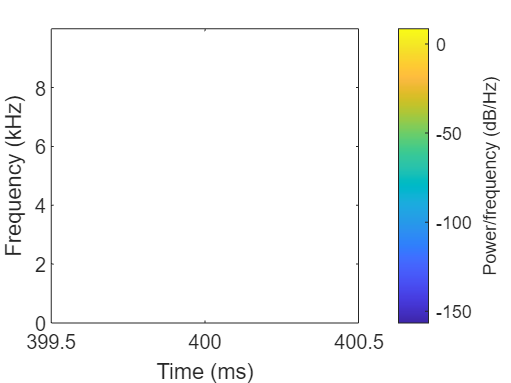

Fs = NFFT;
spectrogram(X,hamming(8000),4000,Fs,Fs,'yaxis')